n = 20;
z_shift=0;
m1 = -sqrt(5/8);
m2 = 1/sqrt(8);
m3 = 1/sqrt(16)+z_shift;
sd1 = 1;
sd2 = 1;
sd3 = 1;
rng(13);
DataX = normrnd(m1,sd1,[n,1]);
DataY = normrnd(m2,sd2,[n,1]);
DataZ = normrnd(m3,sd3,[n,1]);

num_iters = 20000;
burn_in = 10000;
proposal_scale = 0.01

proposal_scale = 0.0100

initial_guess=[1/sqrt(4);1/sqrt(4);(1/sqrt(2)+z_shift)]

initial_guess =     0.5000
    0.5000
    0.7071



ll_function = @(x) ll_density(x,sd1,sd2,sd3,DataX,DataY,DataZ,z_shift);
constraintFunc = @(x) (x(1)^2+x(2)^2+(x(3)-z_shift)^2-1);
dConstraintFunc = @(x) ([2*x(1);2*x(2);2*(x(3)-z_shift)]);

[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess, ll_function, ...
    constraintFunc, dConstraintFunc)

samples =    -0.7336   -0.6975   -0.6213   -0.7252   -0.7881   -0.6989   -0.7696   -0.7964   -0.6646   -0.7344   -0.7859   -0.7953   -0.7052   -0.7052   -0.7173   -0.6994   -0.6787   -0.7931   -0.8348   -0.7652   -0.7058   -0.5820   -0.7586   -0.7701   -0.7110   -0.7180   -0.7311   -0.6858   -0.6858   -0.6471   -0.6221   -0.7005   -0.7854   -0.7854   -0.7854   -0.8129   -0.8570   -0.8757   -0.8950   -0.8457   -0.8457   -0.8693   -0.8122   -0.8509   -0.9101   -0.9473   -0.9314   -0.9532   -0.9598   -0.9552
    0.0125   -0.0087    0.0430    0.0258    0.0259    0.0388    0.1324    0.1218    0.0601    0.0178   -0.0102    0.0654    0.3262    0.3262    0.2666    0.3499    0.4177    0.3456    0.3246    0.3448    0.3863    0.5398    0.3539    0.1657    0.1755    0.2004    0.2150    0.1776    0.1776    0.3100    0.2670    0.3368    0.3718    0.3718    0.3718    0.4621    0.4040    0.3754    0.3731    0.4170    0.4170    0.4704    0.5573    0.5121    0.3985    0.3151    0.3540    0.2250    0.204

accepts =      1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     0     0     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1


mean(accepts)

ans = 0.8886

save("MH_sphereDraws.mat",'samples');

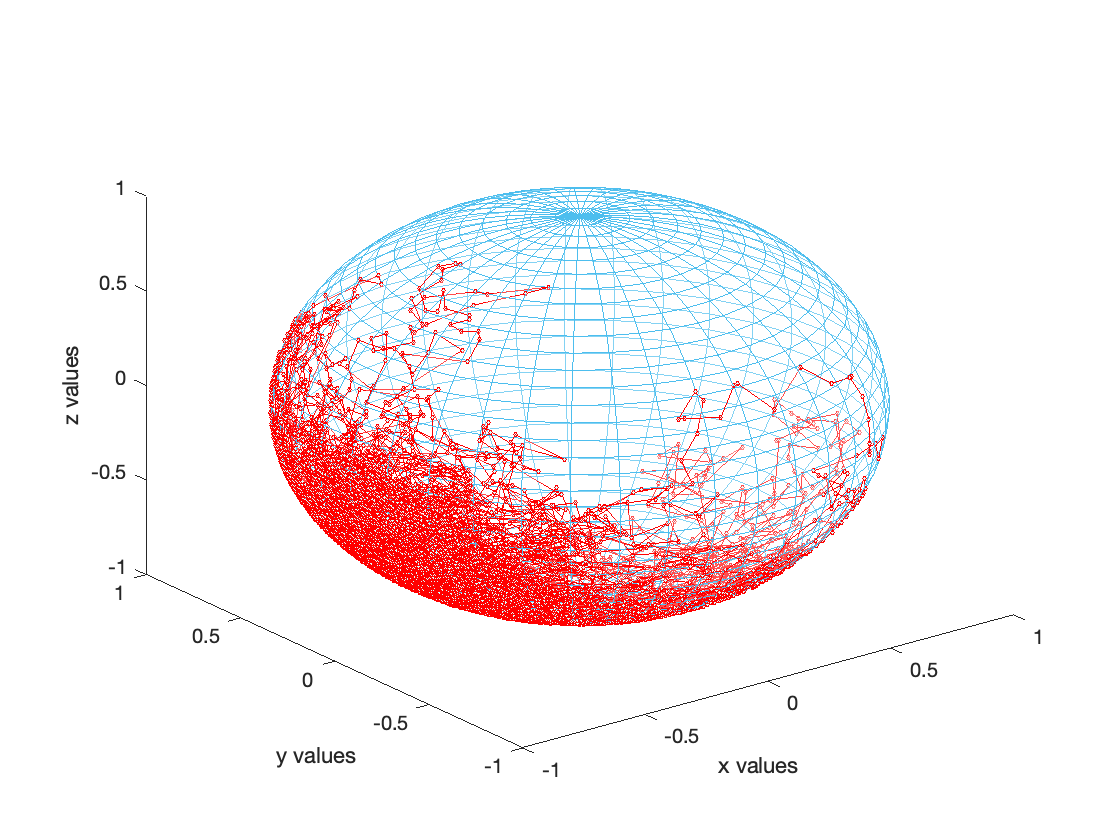

samples=load("MH_sphereDraws.mat");
xs=real(samples.samples(1,:))';
ys=real(samples.samples(2,:))';
zs=real(samples.samples(3,:))';
dim=size(xs);
plot3(xs,ys,zs,'-o','Color','r','MarkerSize',2,'MarkerFaceColor','#D9FFFF')
hold on
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*sin(phi).*cos(theta);
y=rho*sin(phi).*sin(theta);
z=rho*(cos(phi)+z_shift);
mesh(x,y,z,'EdgeColor',[0.3010 0.7450 0.9330],'FaceAlpha',.3)
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
hold off

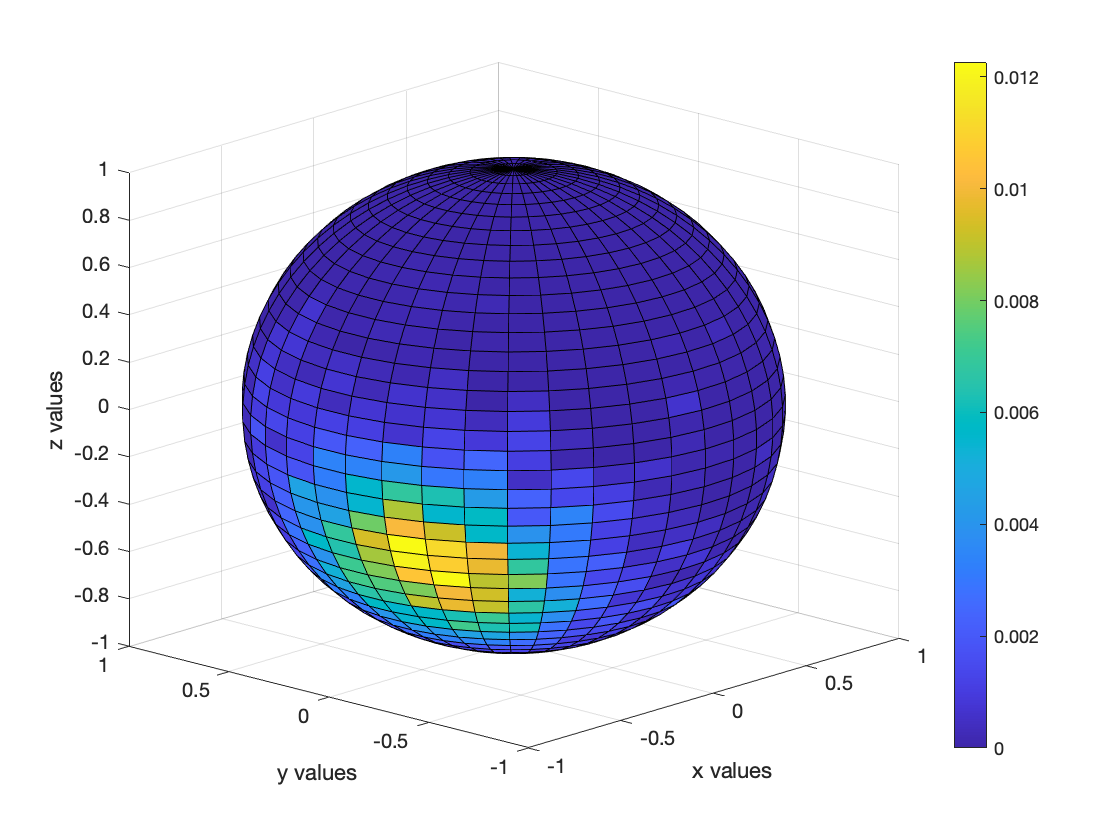

thetas_unshifted=atan(ys./xs);
theta_draws=thetas_unshifted+pi*(xs<0)+...
    2*pi*(xs>0&ys<0);
theta_draws(isnan(theta_draws))=0;
phi_draws=acos(zs-z_shift);

[n,d]=size(theta);
dens2=zeros(n,d);
for t=2:n
    for p=2:d
        x_in= (theta_draws>=theta(p,t-1))&(theta_draws<theta(p,t));
        y_in= (phi_draws>=phi(p-1,t))&(phi_draws<phi(p,t));
        dens2(p,t)=mean(x_in&y_in)*sin(phi(p-1,t-1));
    end
end
s2=surf(x,y,z);
s2.CData=dens2;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])

% h = colorbar;
% set(h, 'ylim', [0 0.45])
% hold on
% % plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off